# Proyecto Final: Moviles y Gravedad

## **Algoritmos Numéricos por Computadora**

## Manuel Fernández 166496

## Bernardo Altamirano 167881

## Santiago Borobia 

## Introducción:

Cuando modelamos dos masas que conviven en un mismo espacio y, por lo tanto, muestran fuerzas de atracción entre ellas lo hacemos de la siguiente manera.

Primero, comencaremos con un ejemplo sencillo que sería modelar la Tierra y Luna en un mismo sistema gravitacional.

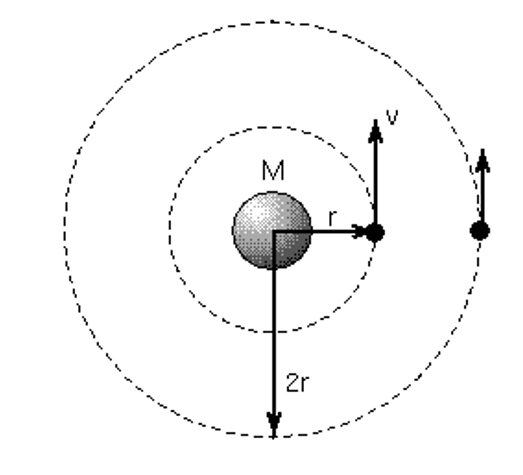

Sea M la masa de la Tierra y sea v la velocidad de un satelite (Luna) que orbita alrededor de la Tierra y, además, sea r el radio que va del centro de la Tierra al centro de la Luna (es decir, distancia de la superficie de la Tierra a la Luna más el radio de la Tierra), entonces sabemos lo siguiente:


$$M_T =\frac{{V_L }^2 r}{G}$$


Por lo tanto, si despejamos la velocidad de la Luna tenemos que:


$$V_L =\sqrt{\frac{GM_t }{r}}$$


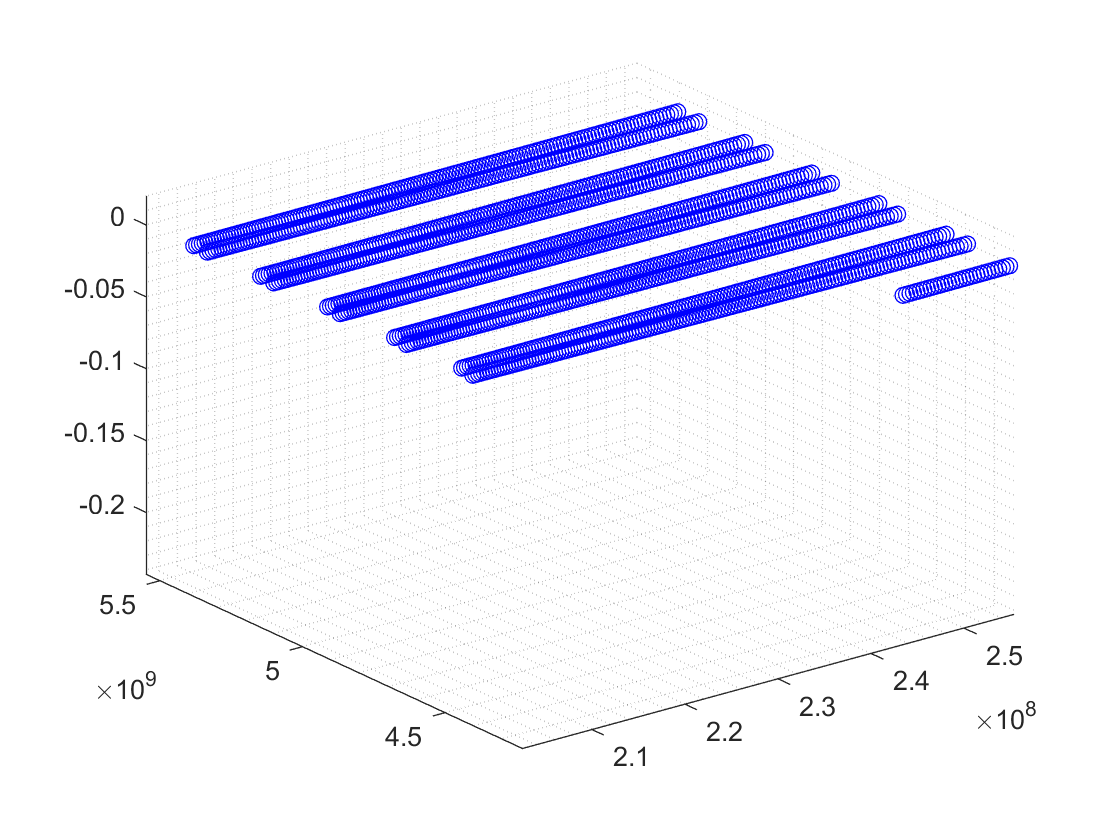

% Un satélite orbitando la Tierra
% La Tierra en el origen (inicialmente)
% El satélite tiene una masa de 20 toneladas 
% y se encuentra a 108 km de altura (eje x)
% Los vectores tienen los datos [Tierra, satélite]
  
% y  = [r;v] 
% y' = [v;a]
% dy/dt = f(t,y)

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mT = 5.9736E+24;              % masa de la Tiera
mL = 7.349e22;                % masa de la Luna
m = [mT, mL]; 

rT = 6371e3;                        % radio de la Tierra m
hL = 384400e3;                      % altura de la superficie de la Tierra a la Luna        
r0 = [ [0;0;0], [rT+hL;0;0] ];      % la posición inicial de la Tierra es en el origen, la del satélite solo varía en la dirección x,
                                    % donde vale la suma del radio de la tierra y la altura del satélite.
vs = sqrt(G * m(1)/r0(1,2));        % velocidad del satélite sigue la fórmula 1.
v0 = [ [0;0;0], [0;vs;0] ];         % la tierra está estacionaria inicialmente, mientras que el satélite tiene una velocidad en y.

ws = vs/(rT+hL);                    % la velocidad angular del satélite sigue la fórmula 2.
T = (2*pi)/ws;                      % periodo en dar una vuelta

h = 60;                 
nv = 4;                 
Nk = nv*ceil(T/h);       
pos = zeros(6,Nk+1);    
pos(:,1) = [r0(:,1);r0(:,2)]; 

%Esto es un rk4
y = [r0;v0];
for t=2:Nk+1
  s1 = f(t,y);
  s2 = f(t+h/2,y+(h/2)*s1);
  s3 = f(t+h/2,y+(h/2)*s2);
  s4 = f(t+h, y+h*s3);
  slope = (s1+2*s2+2*s3+s4)/6;
  %slope = s1; %con esto es euler
  y = y + slope*h;

  r = y(1:3,:); 
  pos(:,t) = [r(:,1);r(:,2)];         
end

plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.k');
grid minor;

function ydot = f(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  dr = r(:,2) - r(:,1);         
  u = dr / norm(dr);            
  dr2 = norm(dr)^2;         	 
  F = (G*m(1)*m(2)/dr2) * u;    
  a = [F/m(1), - F/m(2)];       
  ydot = [v;a];
end